# Cycloidal Disk Design

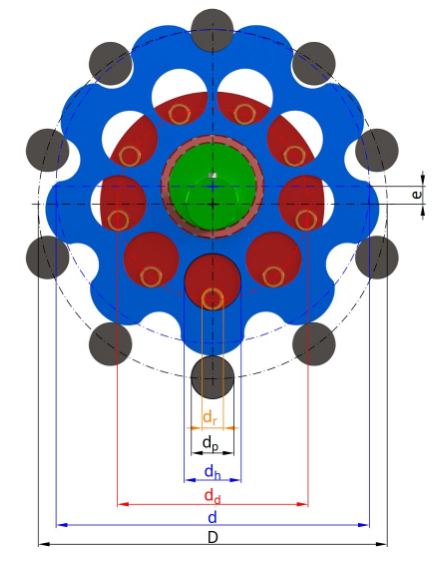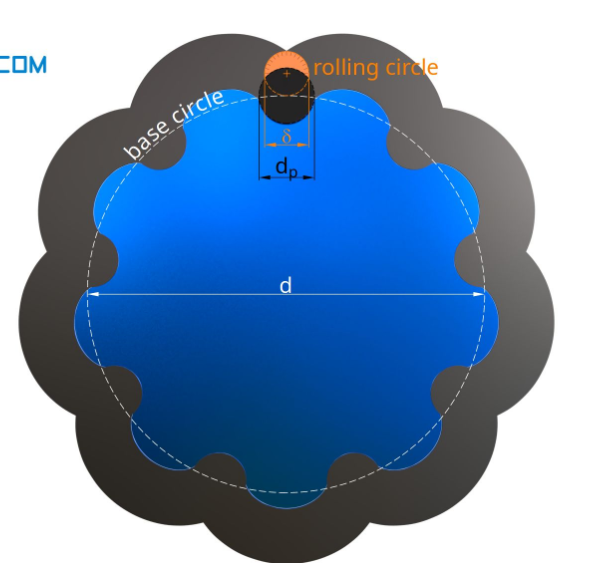

## Equation and Design

clear, clc, clf
% General Equation
syms i N n D d d_d d_h d_p d_r d_cb e delta theta 
EQN1 = i == n/(N-n);
EQN2 = i == d/delta;
EQN3 = delta == D/N;
EQN4 = d == i/N * D;
EQN5 = e <= delta/2;
EQN6 = d_h == d_r + 2*e;
EQN = [EQN1;EQN2;EQN3;EQN4;EQN5;EQN6];

% Outside Ring Gear Profile
X_og = 0 + (D/2)*cos(theta); 
Y_og = 0 + (D/2)*sin(theta);

% Inside Cycloidal Disk Profile
X_ig = 0 + ((d)/2)*cos(theta); 
Y_ig = 0 + ((d)/2)*sin(theta);

% Cycloidal Disk Profile
X_cd =  ( ((D)/2)*cos(theta)) - ((d_p/2)*cos(theta+atan(sin((1-N)*theta)/(((D/2)/(e*N))-cos((1-N)*theta)))))-(e*cos(N*theta));
Y_cd =  (-((D)/2)*sin(theta)) + ((d_p/2)*sin(theta+atan(sin((1-N)*theta)/(((D/2)/(e*N))-cos((1-N)*theta)))))+(e*sin(N*theta));

% Center Bearing
X_cb = 0 + (d_cb/2)*cos(theta); 
Y_cb = 0 + (d_cb/2)*sin(theta);  

% Side Bearing 
X_sb  = 0   + (d_p/2)*cos(theta); 
Y_sb  = 0   + (d_p/2)*sin(theta);

## Input Parameters

% Cycloidal Disk Parameters
D   = 130;                    % Ring Gear diameter                    
d_p = 15;                    % Outside rollers (bearings) diameter 
N   = 11;                    % Number of outside rollers (bearings)
n   = 10;                    % Number of lobe
e   = 5;                    % Eccentric distance
d_r = 15;                    % Inside rollers (bearings) 
d_cb= 40;                    % Center Bearing Diamter        

## Output Parameters

% Calculation
i = n/(N-n);
delta = D/N;
d = D*i/N;
if e > delta/2
    disp("e > delta/2")
end
d_h = d_r + 2*e;

SummaryTable = array2table([i d e d_h delta], "RowNames","Values","VariableNames",["Ratio (i)", "Base Diameter (d)", "Eccentric (e)", "Inside Bearing Diameter (dh)", "Rolling Circle Diameter (Delta)"])

SummaryTable = 1×5 table
              Ratio (i)    Base Diameter (d)    Eccentric (e)    Inside Bearing Diameter (dh)    Rolling Circle Diameter (Delta)
              _________    _________________    _____________    ____________________________    _______________________________

    Values       10             118.18                5                       25                             11.818             


## Plot

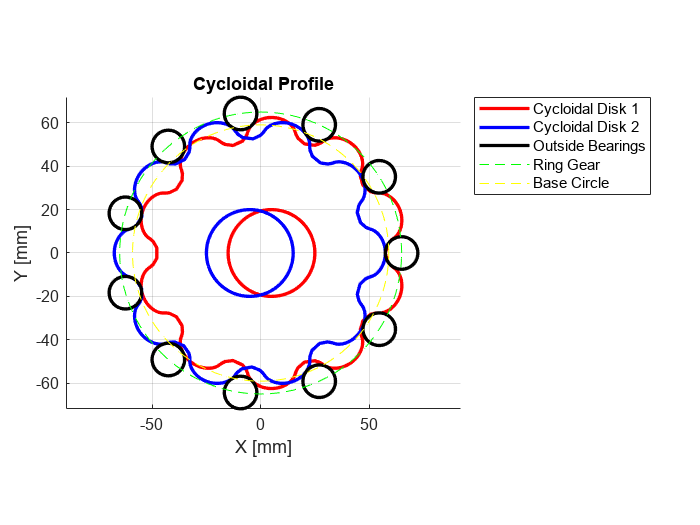

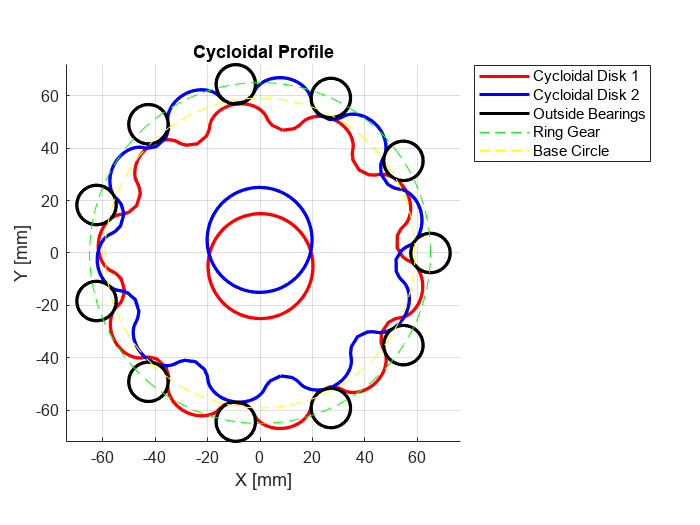

% Plot
frame = 500;
theta = (linspace(0,2*pi, frame))';
x_og = eval(X_og);
y_og = eval(Y_og);
x_ig = eval(X_ig);
y_ig = eval(Y_ig);
x_cd = eval(X_cd);
y_cd = eval(Y_cd);
x_cb = eval(X_cb);
y_cb = eval(Y_cb);
x_sb = eval(X_sb);
y_sb = eval(Y_sb);

clf, figure()
hold on 
for f = 1: length(theta)
    cla
    [X1, Y1]   = cycloidalDisk( e, theta(f)   , [x_cd, y_cd], i, 0);
    [X2, Y2]   = cycloidalDisk(-e, theta(f)+pi, [x_cd, y_cd], i, pi/n);
    [X1c, Y1c] = cycloidalDisk( e, theta(f)   , [x_cb, y_cb], i, 0);
    [X2c, Y2c] = cycloidalDisk(-e, theta(f)+pi, [x_cb, y_cb], i, pi/n);
    plot(X1, Y1, "r", "LineWidth",2)
    plot(X2, Y2, "b", "LineWidth",2)
    plot(X1c, Y1c, "r", "LineWidth",2)
    plot(X2c, Y2c, "b", "LineWidth",2)
    plotBearings(x_sb,y_sb,N,D)
    plot(x_og, y_og,"g--")
    plot(x_ig, y_ig,"y--")
    axis equal
    grid on
    xlabel("X [mm]")
    ylabel("Y [mm]")
    title("Cycloidal Profile")
    legend("Cycloidal Disk 1", "Cycloidal Disk 2","" ,"" , "Outside Bearings","" ,"" ,"" ,"" ,"" ,"" ,"" ,"" ,"" ,"" ,"" , "Ring Gear", "Base Circle", Location="bestoutside"   )
    pause(0.01)
end

hold off

# Supportive Function

function [X, Y] = cycloidalDisk(e, theta, data, ratio, offset)
    x = e*cos(-ratio*theta);
    y = e*sin(-ratio*theta);
    Data = data*R(theta + offset) + [x y];
    X = Data(:,1);
    Y = Data(:,2);
end

function plotBearings(x_sb,y_sb,N,D)
    for j = 0:N
        plot(x_sb + D/2 * cos((j)*((2*pi)/N)) , y_sb + D/2 * sin((j)*((2*pi)/N)), "k", "LineWidth",2, "MarkerFaceColor", "k")
    end
end

function R = R(th)
    R  = [ cos(th) sin(th)
          -sin(th) cos(th) ];
end